**Computer Assignment 1: Spectral Analysis of EEG**

**150207782 Johannes Mämmelä, johannes.mammela@tuni.fi**

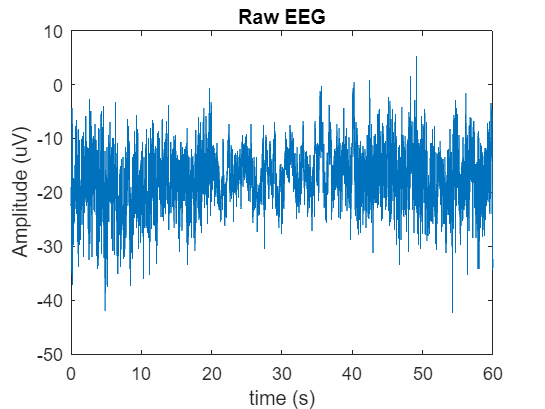

load("BiosignalsA1.mat");

time= linspace(0,60,12182);
EEG=data(:,1);
plot(time,EEG);
title("Raw EEG")
xlabel("time (s)")
ylabel("Amplitude (uV)")

**Task 1:**


fs=1/0.005

fs = 200

N=12310

N = 12310

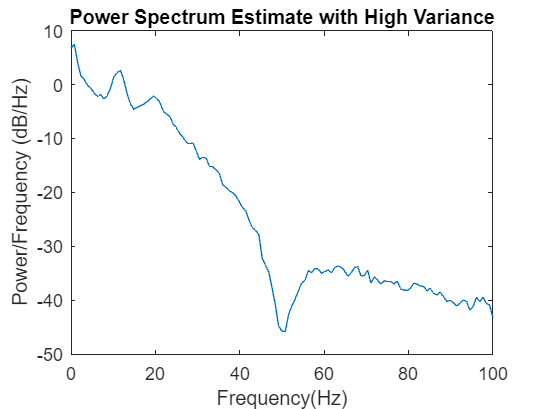

EEG1=EEG-mean(EEG);
figure
[pxx1,f1]=pwelch(EEG1,256,128,256,fs);
plot(f1,10*log10(pxx1));
title("Power Spectrum Estimate with High Variance")
xlabel("Frequency(Hz)")
ylabel("Power/Frequency (dB/Hz)")

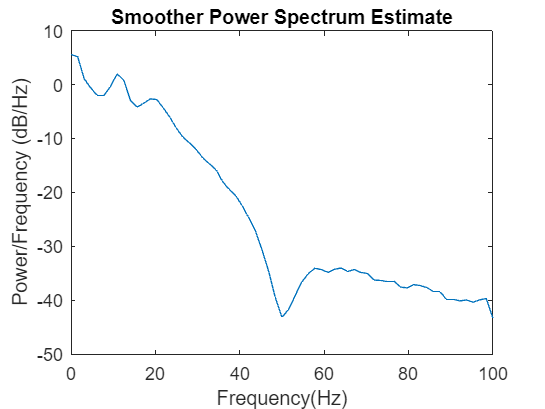


figure
[pxx2,f2]=pwelch(EEG1,128,64,128,fs);
plot(f2,10*log10(pxx2));
title("Smoother Power Spectrum Estimate")
xlabel("Frequency(Hz)")
ylabel("Power/Frequency (dB/Hz)")

**Task 2:**

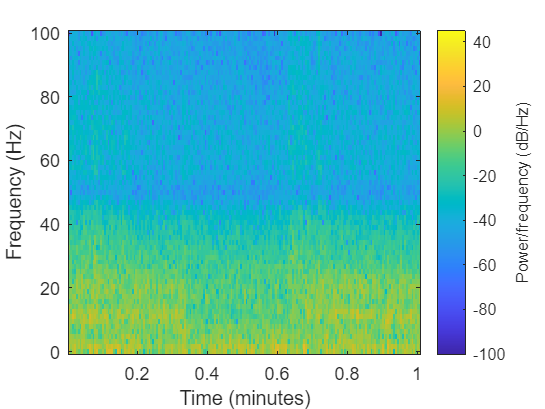

figure
spectrogram(EEG1, 128, 64, 128, fs,"yaxis");
set(gca, 'Clim', [-100 45]);

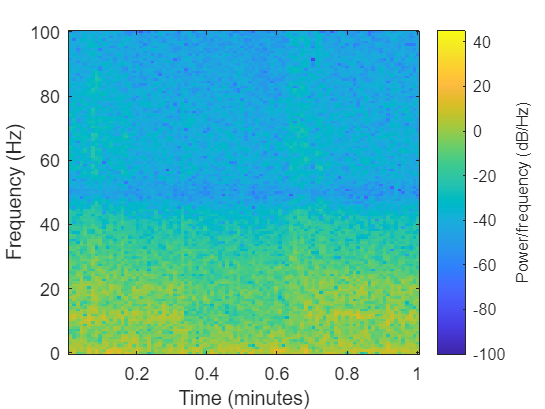


figure
spectrogram(EEG1, 256, 128, 256, fs,"yaxis");
set(gca, 'Clim', [-100 45]);